# MAE 204 FINAL PROJECT (DUE THURSDAY 3/24) AND COMP (3/24)

#### Written by Nandan Seshadri (A59018150)

## Input parameters

addpath("C:\Users\nanda\OneDrive\Desktop\robotics Project\mr")

clear; close; clc; 

% Joint angles
Theta = [0, -(pi/2), pi/4, -(pi/2), -(pi/2), -(pi/4)]';

%Initialising inputs
dt = 0.01; % time step
Max_v = 2; % max joint velocity 
v_e = zeros(6,1);
theta_dot = zeros(6,1); % Joint velocities
error_twist = zeros(6,1);
prev_v_err = 0; % Previous errors

%PI gains
%Gains for best and new task
Kp = 2*eye(6);
Ki = 0*eye(6);

%Gains for overshoot
% Kp = 2*eye(6);
% Ki = 1*eye(6);

% Transformation matrices
M = [ 1 0 0 457; 0 1 0 78; 0 0 1 155; 0 0 0 1];

Tse_i = [[0, 1, 0, 247]; [1, 0, 0, -169]; [0, 0, -1, 782]; [0, 0, 0, 1]];
Tce_g = [[0, 0, 1, 450]; [-1, 0, 0, -300]; [0, -1, 0, 75.25]; [0, 0, 0, 1]];
Tsc_i = [[0, 0, 1, 450]; [-1, 0, 0, -300]; [0, -1, 0, 0]; [0, 0, 0, 1]]; 
Tce_s = [[0, 0, -1, -500]; [1, 0, 0, -300]; [0, -1, 0, 50]; [0, 0, 0, 1]];
Tsc_f = [[0, 0, -1, -500]; [1, 0, 0, -300]; [0, -1, 0, 0]; [0, 0, 0, 1]];

Slist = [[0 0 1 -300 0 0]',[0 1 0 -240 0 0]', [0 1 0 -240 0 244]', [0 1 0 -240 0 457]', [0 0 -1 169 457 0]', [0 1 0 -155 0 457]'];

## Wrapper code

Trajectory = TrajectoryGenerator(Tse_i,Tce_g,Tsc_i,Tce_s,Tsc_f,dt,Slist,M);

% Constructing trajectory matrices for csv
r11 = Trajectory(:,1);
r12 = Trajectory(:,2);
r13 = Trajectory(:,3);
r21 = Trajectory(:,4);
r22 = Trajectory(:,5);
r23 = Trajectory(:,6);
r31 = Trajectory(:,7);
r32 = Trajectory(:,8);
r33 = Trajectory(:,9);
px = Trajectory(:,10);
py = Trajectory(:,11);
pz = Trajectory(:,12);

for i = 1:(length(Trajectory)-1)    
    T_se = FKinSpace(M,Slist,Theta(:,i));
    Tse_d =  [r11(i), r12(i), r13(i), px(i); r21(i), r22(i), r23(i), py(i); r31(i), r32(i), r33(i), pz(i); 0, 0, 0, 1]; % desired transformation matrix
    Tse_dn =  [r11(i+1), r12(i+1), r13(i+1), px(i+1); r21(i+1), r22(i+1), r23(i+1), py(i+1); r31(i+1), r32(i+1), r33(i+1), pz(i+1); 0, 0, 0, 1]; % desired next transformation matrix
    [theta_dot(:,i), Je, error_twist(:,i), v_d, v_e(:,i)] = FeedbackControl(T_se,Tse_d,Tse_dn, Kp, Ki, dt, Slist, prev_v_err, Theta(:,i)); 
    joint_vel = [theta_dot(1,:); theta_dot(2,:); theta_dot(3,:); theta_dot(4,:); theta_dot(5,:); theta_dot(6,:)];
    Theta(:,i+1) = NextState(Theta(:,i),joint_vel(:,i),Max_v,dt);           
end

% Generating csv
fb_gazebo = [Theta',Trajectory(:,13)];
writematrix(Trajectory,'trajectoryOutput.csv'); 
writematrix(fb_gazebo,'trial3.csv')

#### Plotting error twists

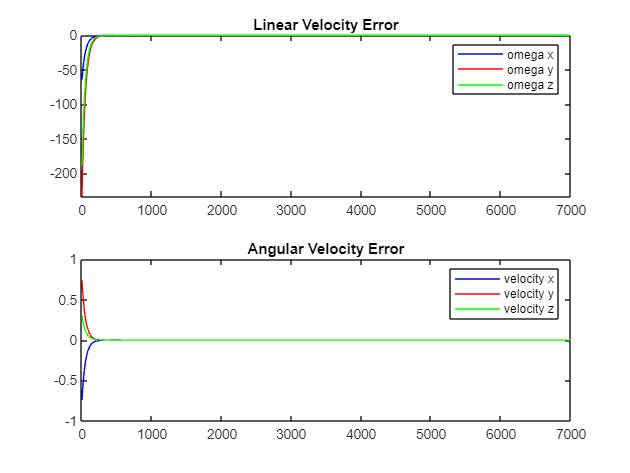

subplot(2,1,1);
plot(error_twist(4,:), 'b');    % plot the fourth row in blue
hold on;
plot(error_twist(5,:), 'r');    % plot the fifth row in red
plot(error_twist(6,:), 'g');    % plot the sixth row in green  
title('Linear Velocity Error');
legend('omega x', 'omega y', 'omega z')
hold off;

subplot(2,1,2);
plot(error_twist(1,:), 'b');  % plot the first row in blue
hold on;
plot(error_twist(2,:), 'r');  % plot the second row in red
plot(error_twist(3,:), 'g');  % plot the third row in green
title('Angular Velocity Error');
legend('velocity x', 'velocity y', 'velocity z')
hold off;

## Functions

#### Trajectory generator

function Trajectory = TrajectoryGenerator(Tse_i,Tce_g,Tsc_i,Tce_s, Tsc_f, dt, Slist, M)

Theta_guess = [-(pi/6), -(pi/2), pi/2, -(pi/2), -(pi/2), 5*(pi/6)]'; % For part B

t = 10;
N = t/dt;
m = 5; % (5 is quintic, 3 is cubic)

for i = 1:t
    if i == 1
        traj1 = CartesianTrajectory(Tse_i, Tce_g, t, N, m);
        traj1_mat = cell2mat(traj1');
        r1_traj1 = traj1_mat(1:4:end,1:3);
        r2_traj1 = traj1_mat(2:4:end,1:3);
        r3_traj1 = traj1_mat(3:4:end,1:3);
        px_traj1 = traj1_mat(1:4:end,4);
        py_traj1 = traj1_mat(2:4:end,4);
        pz_traj1 = traj1_mat(3:4:end,4);
        grip_1 = zeros(N,1); % gripper is open
        Mcat1 = [r1_traj1,r2_traj1,r3_traj1,px_traj1,py_traj1,pz_traj1,grip_1];
    end
    i = i+1;

    if i == 2
        traj2 = ScrewTrajectory(Tce_g, Tsc_i, t, N, m);
        traj2_mat = cell2mat(traj2');
        r1_traj2 = traj2_mat(1:4:end,1:3);
        r2_traj2 = traj2_mat(2:4:end,1:3);
        r3_traj2 = traj2_mat(3:4:end,1:3);
        px_traj2 = traj2_mat(1:4:end,4);
        py_traj2 = traj2_mat(2:4:end,4);
        pz_traj2 = traj2_mat(3:4:end,4);
        grip_2 = zeros(N,1);
        Mcat2 = [r1_traj2,r2_traj2,r3_traj2,px_traj2,py_traj2,pz_traj2,grip_2];
    end
    i = i+1;

    if i == 3
        traj3 = ScrewTrajectory(Tsc_i, Tce_g, t, N, m);
        traj3_mat = cell2mat(traj3');
        r1_traj3 = traj3_mat(1:4:end,1:3);
        r2_traj3 = traj3_mat(2:4:end,1:3);
        r3_traj3 = traj3_mat(3:4:end,1:3);
        px_traj3 = traj3_mat(1:4:end,4);
        py_traj3 = traj3_mat(2:4:end,4);
        pz_traj3 = traj3_mat(3:4:end,4);
        grip_3 = ones(N,1); %gripper is closed
        Mcat3 = [r1_traj3,r2_traj3,r3_traj3,px_traj3,py_traj3,pz_traj3,grip_3];
    end
    i = i+1;

    % Comp exam
    % part A
%     if i == 4  
%         [thetastart, ~] = IKinSpace(Slist, M, Tce_g, Theta_guess, 0.01, 0.001);
%         thetaend = thetastart + [pi, 0, 0, 0, 0, 0]';
%         joint_theta = JointTrajectory(thetastart, thetaend, t, N, m);
%         traj4_mat = zeros(4000, 4);
%         for j = 1:length(joint_theta)
%             traj4_init = FKinSpace(M, Slist, joint_theta(j,:)');
%             traj4_mat(4*(j-1)+1:4*(j-1)+4,1:4) = traj4_init;
%         end
%         r1_traj4 = traj4_mat(1:4:end,1:3);
%         r2_traj4 = traj4_mat(2:4:end,1:3);
%         r3_traj4 = traj4_mat(3:4:end,1:3);
%         px_traj4 = traj4_mat(1:4:end,4);
%         py_traj4 = traj4_mat(2:4:end,4);
%         pz_traj4 = traj4_mat(3:4:end,4);
%         grip_4 = ones(N,1);
%         Mcat4 = [r1_traj4,r2_traj4,r3_traj4,px_traj4,py_traj4,pz_traj4,grip_4];
%     end
%     i = i+1;
% 
%     if i == 5   
%         traj5 = ScrewTrajectory(traj4_init, Tce_s, t, N, m);
%         traj5_mat = cell2mat(traj5');
%         r1_traj5 = traj5_mat(1:4:end,1:3);
%         r2_traj5 = traj5_mat(2:4:end,1:3);
%         r3_traj5 = traj5_mat(3:4:end,1:3);
%         px_traj5 = traj5_mat(1:4:end,4);
%         py_traj5 = traj5_mat(2:4:end,4);
%         pz_traj5 = traj5_mat(3:4:end,4);
%         grip_5 = ones(N,1);
%         Mcat5 = [r1_traj5,r2_traj5,r3_traj5,px_traj5,py_traj5,pz_traj5,grip_5];
%     end
%     i = i+1;
% 
%     if i == 6
%         traj7 = ScrewTrajectory(Tce_s, Tsc_f, t, N, m);
%         traj7_mat = cell2mat(traj7');
%         r1_traj6 = traj7_mat(1:4:end,1:3);
%         r2_traj6 = traj7_mat(2:4:end,1:3);
%         r3_traj6 = traj7_mat(3:4:end,1:3);
%         px_traj6 = traj7_mat(1:4:end,4);
%         py_traj6 = traj7_mat(2:4:end,4);
%         pz_traj6 = traj7_mat(3:4:end,4);
%         grip_6 = ones(N,1);
%         Mcat6 = [r1_traj6,r2_traj6,r3_traj6,px_traj6,py_traj6,pz_traj6,grip_6];
%     end
%     i=i+1;
%     if i == 7
%         traj7 = ScrewTrajectory(Tsc_f,Tce_s, t, N, m);
%         traj7_mat = cell2mat(traj7');
%         r1_traj7 = traj7_mat(1:4:end,1:3);
%         r2_traj7 = traj7_mat(2:4:end,1:3);
%         r3_traj7 = traj7_mat(3:4:end,1:3);
%         px_traj7 = traj7_mat(1:4:end,4);
%         py_traj7 = traj7_mat(2:4:end,4);
%         pz_traj7 = traj7_mat(3:4:end,4);
%         grip_7 = zeros(N,1);
%         Mcat7 = [r1_traj7,r2_traj7,r3_traj7,px_traj7,py_traj7,pz_traj7,grip_7];
%     end
% 
%     Trajectory = [Mcat1;Mcat2;Mcat3;Mcat4;Mcat5;Mcat6;Mcat7];   % Part A
% 
% end
% end


%% Uncomment for part B 
    % part B    
%     if i == 4
%         [theta1, ~] = IKinSpace(Slist, M, Tce_g, Theta_guess, 0.01, 0.001);
%         theta2 = theta1 + [0, 0, -pi, 0, 0, 0]';
% %         theta1 = [-0.29538818823128077, -0.8611390547500877, 1.3650331323536076, -2.074690404398421, -1.5707963267948613, 2.8462044653585394]';
%         joint_theta1 = JointTrajectory(theta1, theta2, t, N, m);
%         traj5_mat = zeros(4000, 4);
%         for j = 1:length(joint_theta1)
%             traj5_init = FKinSpace(M, Slist, joint_theta1(j,:)');
%             traj5_mat(4*(j-1)+1:4*(j-1)+4,1:4) = traj5_init;
%         end
%         r1_traj4 = traj5_mat(1:4:end,1:3);
%         r2_traj4 = traj5_mat(2:4:end,1:3);
%         r3_traj4 = traj5_mat(3:4:end,1:3);
%         px_traj4 = traj5_mat(1:4:end,4);
%         py_traj4 = traj5_mat(2:4:end,4);
%         pz_traj4 = traj5_mat(3:4:end,4);
%         grip_4 = ones(N,1);
%         Mcat4 = [r1_traj4,r2_traj4,r3_traj4,px_traj4,py_traj4,pz_traj4,grip_4];
%     end
%     i = i+1;
% 
%     if i == 5
%         [theta1, ~] = IKinSpace(Slist, M, Tce_g, Theta_guess, 0.01, 0.001);
%         theta2 = theta1 + [0, 0, -pi, 0, 0, 0]';
%         theta3 = theta1 + [0, 0, -pi, 0, +pi, 0]';
%         joint_theta1 = JointTrajectory(theta2, theta3, t, N, m);
%         traj5_mat = zeros(4000, 4);
%         for j = 1:length(joint_theta1)
%             traj5_init = FKinSpace(M, Slist, joint_theta1(j,:)');
%             traj5_mat(4*(j-1)+1:4*(j-1)+4,1:4) = traj5_init;
%         end
%         r1_traj5 = traj5_mat(1:4:end,1:3);
%         r2_traj5 = traj5_mat(2:4:end,1:3);
%         r3_traj5 = traj5_mat(3:4:end,1:3);
%         px_traj5 = traj5_mat(1:4:end,4);
%         py_traj5 = traj5_mat(2:4:end,4);
%         pz_traj5 = traj5_mat(3:4:end,4);
%         grip_5 = ones(N,1);
%         Mcat5 = [r1_traj5,r2_traj5,r3_traj5,px_traj5,py_traj5,pz_traj5,grip_5];               
%     end
%     i = i+1;
% 
%     if i == 6
%         traj6 = ScrewTrajectory(traj5_init, Tce_s, t, N, m);
%         traj6_mat = cell2mat(traj6');
%         r1_traj6 = traj6_mat(1:4:end,1:3);
%         r2_traj6 = traj6_mat(2:4:end,1:3);
%         r3_traj6 = traj6_mat(3:4:end,1:3);
%         px_traj6 = traj6_mat(1:4:end,4);
%         py_traj6 = traj6_mat(2:4:end,4);
%         pz_traj6 = traj6_mat(3:4:end,4);
%         grip_6 = ones(N,1);
%         Mcat6 = [r1_traj6,r2_traj6,r3_traj6,px_traj6,py_traj6,pz_traj6,grip_6];
%     end
%     i = i+1;
%     
%     if i == 7
%         traj8 = ScrewTrajectory(Tce_s, Tsc_f, t, N, m);
%         traj8_mat = cell2mat(traj8');
%         r1_traj7 = traj8_mat(1:4:end,1:3);
%         r2_traj7 = traj8_mat(2:4:end,1:3);
%         r3_traj7 = traj8_mat(3:4:end,1:3);
%         px_traj7 = traj8_mat(1:4:end,4);
%         py_traj7 = traj8_mat(2:4:end,4);
%         pz_traj7 = traj8_mat(3:4:end,4);
%         grip_7 = ones(N,1);
%         Mcat7 = [r1_traj7,r2_traj7,r3_traj7,px_traj7,py_traj7,pz_traj7,grip_7];
%     end
%     i=i+1;
% 
%     if i == 8
%         traj8 = ScrewTrajectory(Tsc_f,Tce_s, t, N, m);
%         traj8_mat = cell2mat(traj8');
%         r1_traj8 = traj8_mat(1:4:end,1:3);
%         r2_traj8 = traj8_mat(2:4:end,1:3);
%         r3_traj8 = traj8_mat(3:4:end,1:3);
%         px_traj8 = traj8_mat(1:4:end,4);
%         py_traj8 = traj8_mat(2:4:end,4);
%         pz_traj8 = traj8_mat(3:4:end,4);
%         grip_8 = zeros(N,1);
%         Mcat8 = [r1_traj8,r2_traj8,r3_traj8,px_traj8,py_traj8,pz_traj8,grip_8];
%     end  
% 
%     Trajectory = [Mcat1;Mcat2;Mcat3;Mcat4;Mcat5;Mcat6;Mcat7;Mcat8];   % Part 8

%  Test
    if i == 4  
        [thetastart, ~] = IKinSpace(Slist, M, Tce_g, Theta_guess, 0.01, 0.001);
        thetaend = thetastart + [pi, 0, 0, 0, 0, 0]';
        joint_theta = JointTrajectory(thetastart, thetaend, t, N, m);
        traj4_mat = zeros(4000, 4);
        for j = 1:length(joint_theta)
            traj4_init = FKinSpace(M, Slist, joint_theta(j,:)');
            traj4_mat(4*(j-1)+1:4*(j-1)+4,1:4) = traj4_init;
        end
        r1_traj4 = traj4_mat(1:4:end,1:3);
        r2_traj4 = traj4_mat(2:4:end,1:3);
        r3_traj4 = traj4_mat(3:4:end,1:3);
        px_traj4 = traj4_mat(1:4:end,4);
        py_traj4 = traj4_mat(2:4:end,4);
        pz_traj4 = traj4_mat(3:4:end,4);
        grip_4 = ones(N,1);
        Mcat4 = [r1_traj4,r2_traj4,r3_traj4,px_traj4,py_traj4,pz_traj4,grip_4];
    end
    i = i+1;

    if i == 5   
        traj5 = ScrewTrajectory(traj4_init, Tce_s, t, N, m);
        traj5_mat = cell2mat(traj5');
        r1_traj5 = traj5_mat(1:4:end,1:3);
        r2_traj5 = traj5_mat(2:4:end,1:3);
        r3_traj5 = traj5_mat(3:4:end,1:3);
        px_traj5 = traj5_mat(1:4:end,4);
        py_traj5 = traj5_mat(2:4:end,4);
        pz_traj5 = traj5_mat(3:4:end,4);
        grip_5 = ones(N,1);
        Mcat5 = [r1_traj5,r2_traj5,r3_traj5,px_traj5,py_traj5,pz_traj5,grip_5];
    end
    i = i+1;

    if i == 6
        traj7 = ScrewTrajectory(Tce_s, Tsc_f, t, N, m);
        traj7_mat = cell2mat(traj7');
        r1_traj6 = traj7_mat(1:4:end,1:3);
        r2_traj6 = traj7_mat(2:4:end,1:3);
        r3_traj6 = traj7_mat(3:4:end,1:3);
        px_traj6 = traj7_mat(1:4:end,4);
        py_traj6 = traj7_mat(2:4:end,4);
        pz_traj6 = traj7_mat(3:4:end,4);
        grip_6 = ones(N,1);
        Mcat6 = [r1_traj6,r2_traj6,r3_traj6,px_traj6,py_traj6,pz_traj6,grip_6];
    end
    i=i+1;
    if i == 7
        traj7 = ScrewTrajectory(Tsc_f,Tce_s, t, N, m);
        traj7_mat = cell2mat(traj7');
        r1_traj7 = traj7_mat(1:4:end,1:3);
        r2_traj7 = traj7_mat(2:4:end,1:3);
        r3_traj7 = traj7_mat(3:4:end,1:3);
        px_traj7 = traj7_mat(1:4:end,4);
        py_traj7 = traj7_mat(2:4:end,4);
        pz_traj7 = traj7_mat(3:4:end,4);
        grip_7 = zeros(N,1);
        Mcat7 = [r1_traj7,r2_traj7,r3_traj7,px_traj7,py_traj7,pz_traj7,grip_7];
    end

    Trajectory = [Mcat1;Mcat2;Mcat3;Mcat4;Mcat5;Mcat6;Mcat7];   % Part A

    end
end

#### Next state

function thetalist = NextState(thetalist,joint_vel,Max_vel,dt)
    if joint_vel >= Max_vel
        joint_vel = Max_vel;
    end
    thetalist = thetalist+(joint_vel*dt); % Eulers equation
end

#### Feedback control

function [theta_dot, Je, error_twist,v_d,v_e] = FeedbackControl(T_se, Tse_d, Tse_dn, Kp, Ki, delta_t, Slist, v_i, Theta)
    error_twist = se3ToVec(MatrixLog6(TransInv(T_se)*Tse_d)); 
    v_d = se3ToVec((1/delta_t)*MatrixLog6((TransInv(Tse_d)*Tse_dn)));
    v_adj = Adjoint(TransInv(T_se)*Tse_d); 
    v_i = v_i + delta_t*error_twist; 
    v_e = v_adj*v_d + Kp*error_twist + Ki*v_i;
    Je = Adjoint(TransInv(Tse_d))*JacobianSpace(Slist, Theta);
    theta_dot = pinv(Je)*v_e;
end